# `coord` documentation

`coord` is part of Antarctic Mapping Tools for Matlab (Greene et al., 2017). See `List_of_Functions.mlx` for a complete list of functions in AMT. 

The `coord` function returns coordinates from mouse clicks. This function was written for the Antarctic Mapping Toolbox. 

After calling coord, the current figure title will change to let you know you can start clicking. Here are the commands: 

## Syntax

## Description

`coord` without any inputs prints coordinates of mouse clicks to the Command Window in a two-column format,| [lat lon]| or `[x y]`. Coordinates have the units of the current axes unless `'geo'` or `'xy'` are specified. 

`[lat,lon] = coord('geo')` specifies that you want outputs in geographic coordinates, even if you are clicking around on a polar stereographic x/y map. 

`[x,y] = coord('xy')` returns coordinates in polar stereographic (ps71) coordinates. 

`[...] = coord(,...'MarkerProperty',MarkerValue)` specifies marker properties for when you're clickin' around on the map. 

`[...] = coord(...,'keep')` prevents coord from automatically deleting markers upon exiting the user interface. 

`[...,h] = coord(...)` returns a handle `h` of any plotted markers. 

## Example 1: With the Matlab's Mapping Toolbox

Get some coordinates from clicking around in map coordinates. Below I'm initializing a map with `bedmap2` then I'll click once on the Antarctic Peninsula and a second time in East Anarctica: 

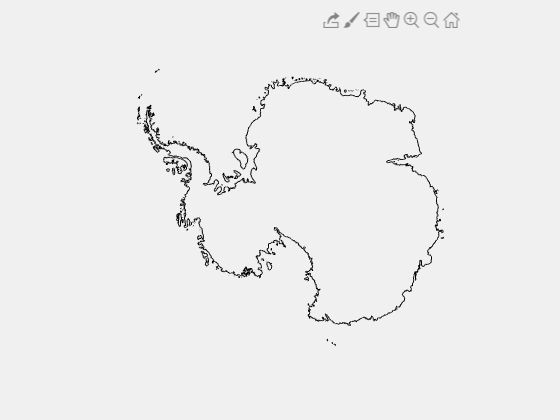

lat =   -85.2272
  -74.4138


lon =   -29.1481
  123.5275


bedmap2 gl 
[lat,lon] = coord  % (<--click around on the map and press enter when you're satisfied)

By default, the markers disappear after hitting Enter, but you can see from the coordinates that I clicked here: 

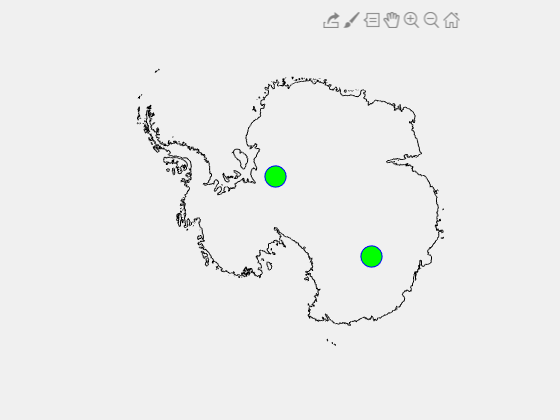

plotm(lat,lon,'bo','markersize',16,'markerfacecolor','g')

## Example 2: Also with Matlab's Mapping Toolbox:

This example is a little more involved. Return polar stereographic coordinates, make the makers large red pentagrams, and use the `'keep'` option to retain the markers upon hitting Return:

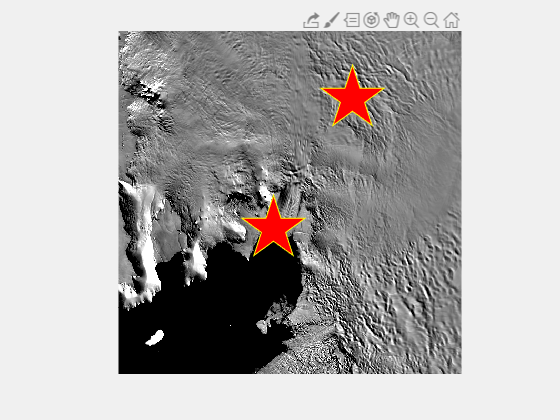

x = 	1.0e+06 *

   -1.5068
   -1.6192


y = 	1.0e+05 *

   -1.3332
   -3.1839


modismoa 'pine island glacier'
[x,y] = coord('xy','marker','p','markerfacecolor','r','markersize',50,'keep')

## Example 3: No Mapping Toolbox Required:

If you start in polar stereographic meters, coordinates are automatically returned in polar stereographic meters unless you specify `'geo'`: 

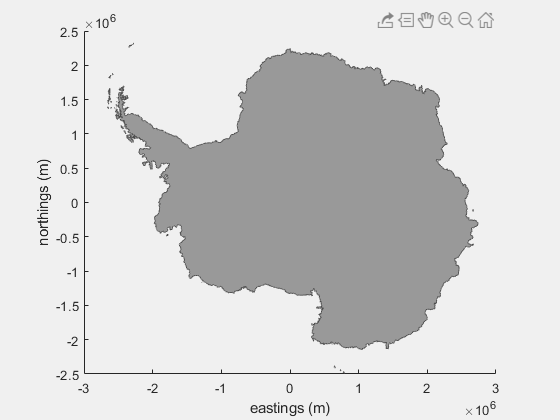

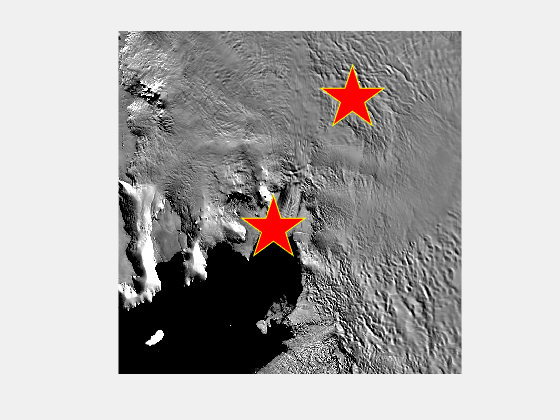

x = 	1.0e+06 *

   -0.8673
    1.8878


y = 	1.0e+05 *

    3.3528
   -8.4548


figure
bedmap2('patch coast','xy') 
xlabel 'eastings (m)' 
ylabel 'northings (m)' 
[x,y] = coord

Alternatively, specify `'geo'` and click on the very same map get geo coordinates: 

lat =   -76.3518
  -81.3756


lon =    45.9912
 -148.6548


[lat,lon] = coord('geo')

## Citing AMT

If this function or any other part of Antarctic Mapping Tools is useful for you, please cite the paper that describes AMT. 

Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function was written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas at Austin's Institute for Geophysics (UTIG) in November 2015.